Ligning at kunne

U er overall heat transfer coefficient.

3.28

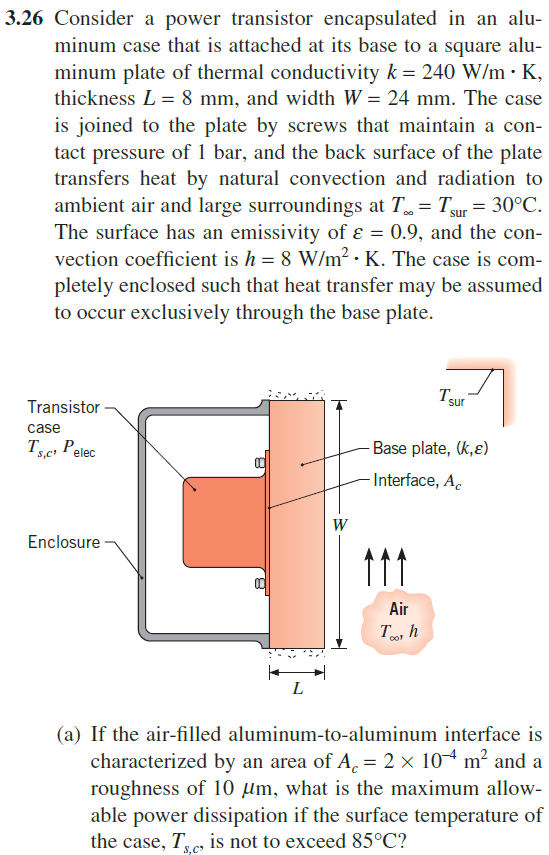

clear all

k = 240; % W/(m*K)
L = 0.008; %m %længde
W = 0.024;%m
T_inf = 30+273.15; % K
T_sur = T_inf;
epsilon = 0.9;
h = 8; % W/(M^2 * K) 
A_plate = W^2; % Area of square plate
A_c =2e-4;
mu = 10e-6;
T_sc = 85 + 273.15; %K
sigma = 5.670374419 * 10^-8; % J/K %stefan-boltzman konstant
R_tc = 2.75e-4; %m^2 * K/ W % Thermal Resistance fra Table 3.1 side 106 (husk det er 10^-4)

 * A

 * A

Det antages at varmen spredes instantat til hele højden af pladen og derefter går igennem pladen.

Da vi har steady state er q ens igennem alle modstande.

steady state dT/dt = 0 

(1) Steady-state, 

(2) Negligible heat transfer from the enclosure, to the surroundings. 

(3) One-dimensional conduction in the base plate, 

(4) Radiation exchange at surface of base plate is with large surroundings, (5) Constant thermal conductivity.

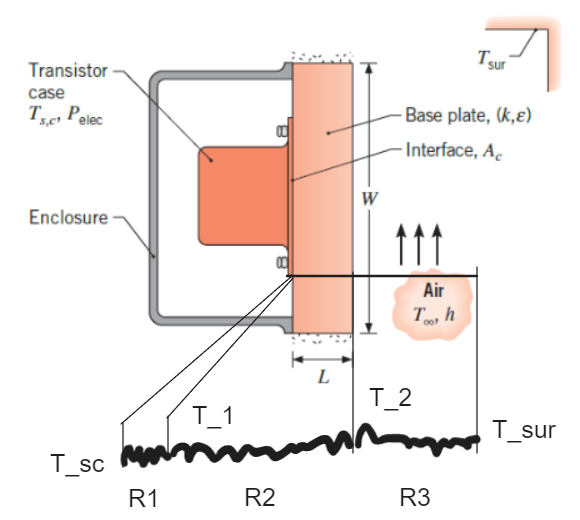

syms T_1 T_2 q T_var
T_2 = sym("T_2", "real");
T_2 = sym("T_2", "positive");

h_r = epsilon * sigma * (T_2 +T_sur) * (T_2^2 +T_sur^2); %ligning 1.9

% q_saml = (T_sc - T_1)/R_tc
% q_cond = -k*A_plate/L * (T_1 - T_2)

R1 = R_tc/A_c %modstanden af plade samlingen

R1 = 1.3750

R2 = L/(k *A_plate) %modstanden igennem pladen

R2 = 0.0579

Vi samler de to ligninger således vi eliminere $T_1$

q_smal_cond_eq = (T_sc - T_2)/ (R1 + R2);

q_conv = h * A_plate * (T_2 - T_inf);
q_rad = epsilon * sigma * (T_2^4 - T_sur^4) * A_plate; % = h_r * A_plate * (T_2 - T_sur) % 

R3 er paralel forbindelse imellem R3_conv og R3_rad

R3_conv = 1/(h*A_plate);
R3_rad = 1/(h_r*A_plate);
R3 = 1/(1/R3_conv + 1/R3_rad);

q_conv_rad_eq  = q_conv + q_rad % bruger overflade temperaturen som ligevægts punkt og finder T_s

$$q\_conv\_rad\_eq = \frac{69407503175365443\,{T_{2}}^{4}}{2361183241434822606848000000}+\frac{72\,T_{2}}{15625}-\frac{20366284418783428455829683106813593}{12379400392853802748991242240000000}$$

Vi sætter de to fundne ligninger lig med hinanden

T_2_sol = solve(q_smal_cond_eq == q_conv_rad_eq, T_2);
T_2_sol_ = vpa(T_2_sol, 5)% - 273.75

$$T\_2\_sol\_ = 357.46$$


q = (T_sc - T_sur)/(R1 + R2 + subs(R3, T_2, T_2_sol));

P_elec = vpa(q,5)

$$P\_elec = 0.48193$$

h_lin = linspace(4,200, 200-3);
T_2_sol = [];
qs = [];

for i = 1:length(h_lin)
    q_conv = h_lin(i) * A_plate * (T_2 - T_inf);
    q_conv_rad_eq  = q_conv + q_rad; % = (T_2 - T_inf)/ R3

    T_2_sol(i) = solve(q_smal_cond_eq == q_conv_rad_eq, T_2);
    % vpa(T_2_sol, 5)% - 273.75
    
    qs(i) = (T_sc - T_sur)/(R1 + subs(R2, h, h_lin(i)) + subs(R3, T_2, T_2_sol(i)));
end

sanity_check_q = qs(5)

sanity_check_q = 0.4819

sanity_check_h_lin = h_lin(5)

sanity_check_h_lin = 8

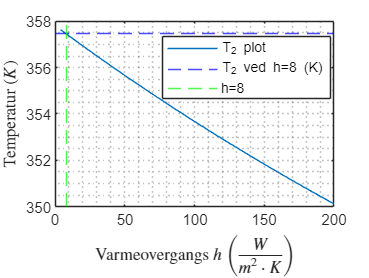


plot(h_lin, T_2_sol, 'DisplayName','T_2 plot')
grid('minor')
% yline(T_sc, 'b--', 'DisplayName','T_sc (K)')
yline(double(T_2_sol_), 'b--', 'DisplayName','T_2 ved h=8 (K)')
xline(h,'g--', 'DisplayName','h=8')
xlabel("Varmeovergangs $h$ $\left(\frac{W}{m^2 \cdot K}\right)$", Interpreter="latex")
ylabel("Temperatur $(K)$", Interpreter="latex")
legend('Location','best')

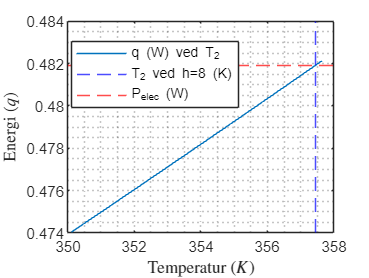



plot(T_2_sol, qs, 'DisplayName','q (W) ved T_2')
grid('minor')
xline(double(T_2_sol_), 'b--', 'DisplayName','T_2 ved h=8 (K)')
yline(double(P_elec), 'r--', 'DisplayName','P_elec (W)')
ylabel("Energi $(q)$", Interpreter="latex")
xlabel("Temperatur $(K)$", Interpreter="latex")
legend('Location','best')

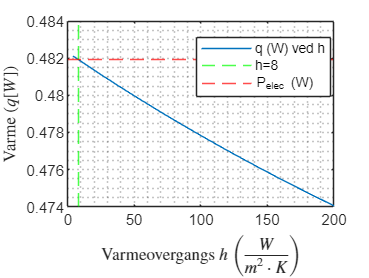



plot(h_lin, qs, 'DisplayName','q (W) ved h')
grid('minor')
xline(h,'g--', 'DisplayName','h=8')
yline(double(P_elec), 'r--', 'r--', 'DisplayName','P_elec (W)')
ylabel("Varme $(q [W])$", Interpreter="latex")
xlabel("Varmeovergangs $h$ $\left(\frac{W}{m^2 \cdot K}\right)$", Interpreter="latex")
legend('Location','best')

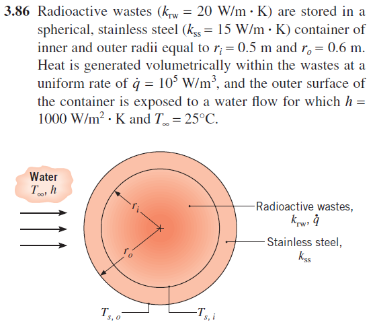

Find overflade temperaturen

energi balnce

clear all
clf
k_rw = 20; % W/m*K
k_ss = 15; % W/m*K
r_i = 0.5; %m
r_o = 0.6; % m
q_dot = 1e5; % W/m^3
h = 1000; % W/m^2*K
T_inf = 25 + 273.15; % K

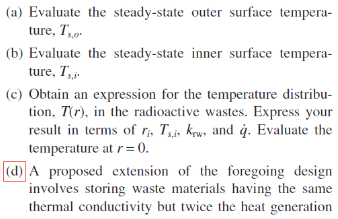

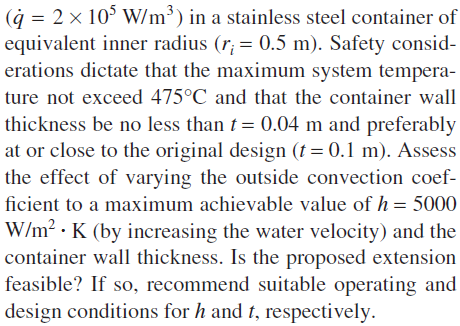

(a)

Bruger Gauss's law  eqvivalent


$$q(r) = \int \dot q\ dV = \dot q  \frac{4}{3} \pi r^3$$


Vi finder T_s,o ved at gå igennem film laget hvor den totale varme der kommer ud er q genneret af kernen

varmegeneration i volumen er ens med den energi der skal væk via konvection for at få steady state.


$$E_{gen} - E_{out} = 0$$


syms T_so T_si
assume(T_so, 'real')
q_gen = q_dot * 4/3 * pi * r_i^3;
A_o = 4*pi*r_o^2;
q_conv = h*A_o *(T_so - T_inf);

T_so_ = solve(q_gen == q_conv, T_so);
T_so_sol = double(vpa(T_so_, 6))

T_so_sol = 309.7241

T_so_C = T_so - 273.15

$$T\_so\_C = T_{\mathrm{so}}-\frac{5463}{20}$$

q_conv = subs(q_conv,T_so, T_so_sol)

$$q\_conv = \frac{71582788266669\,\pi }{4294967296}$$

(b)

Vi laver en energi balance ved indersiden af skallen


$$E_{in} - E_{out} = 0$$


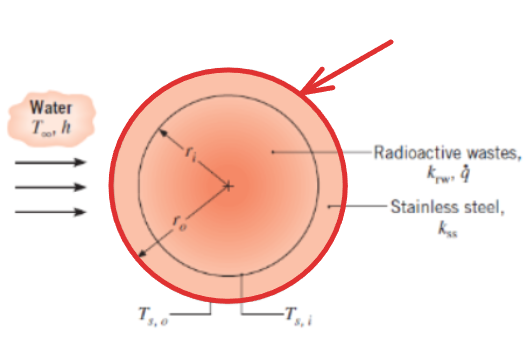

R_cond =(3.41)

q = 

konductionen sætte lig konvectionen


q_cond = (T_si - T_so_sol) * 4 * pi * k_ss /(1/r_i - 1/r_o)

$$q\_cond = 45\,\pi \,\left(4\,T_{\mathrm{si}}-\frac{42568152605825}{34359738368}\right)$$


T_si_ = solve(q_conv == q_cond, T_si);
T_si = double(vpa(T_si_, 6))

T_si = 402.3167

T_si_C = T_si - 273.15

T_si_C = 129.1667

(c)

ligning 2.29

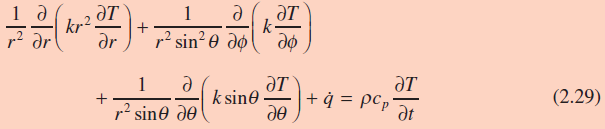

Vi bruger tabel 3.3 til at finde løsningen til heat equation for en kugle

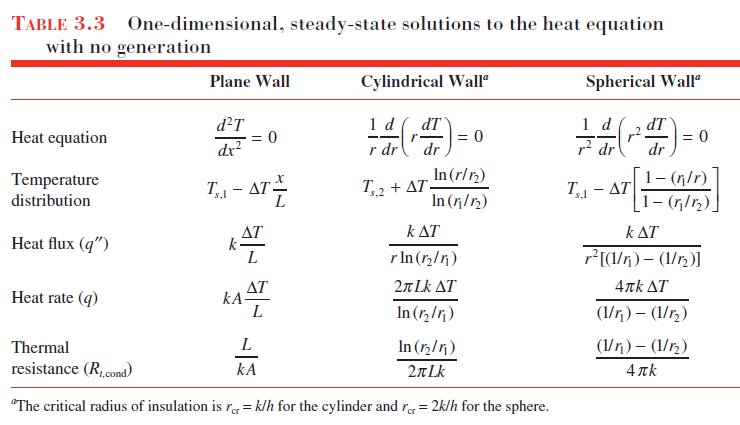

Fra 1 dementionel varme ligning med varme generation

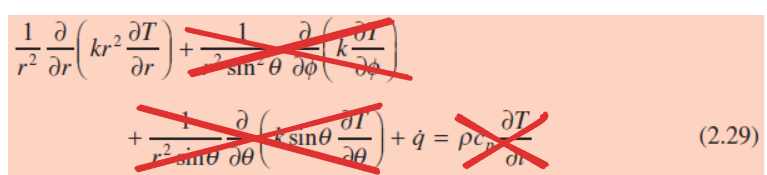


$$\frac{1}{r^2}\frac{\partial}{\partial r} \left(kr^2 \frac{\partial T}{\partial r}\right) + \dot{q} = 0$$



$$k_{rw}\frac{\partial}{\partial r} \left(r^2 \frac{\partial T}{\partial r}\right) + r^2 \dot{q} = 0$$


med speration af variable får vi


$$\int k_{rw}\ \partial \left(r^2 \frac{\partial T}{\partial r}\right)= - \int r^2 \dot{q}\ \partial r$$



$$k_{rw}  r^2 \frac{\partial T}{\partial r} = - \frac{r^3}{3} \dot{q} + C1$$



$$\int \partial T = - \int \frac{r}{3k_{rw}} \dot{q}\ \partial r + \int \frac{C1}{r^2}\ \partial r $$



$$T = - \frac{r^2}{6k_{rw}} \dot{q} - \frac{C1}{r} + C2$$


$C1 = \frac{\partial T}{\partial r} = 0$ konstant temepratur i centrum


$$C2 = T(r_i) = T_{si}$$


$T(r) = \frac{\dot{q} }{6k_{rw}} (r_i^2 - r^2) + T_{si}$  ($T_{si}$ ved $r_{i}$)

syms T(r) r T_rw
T(r) = q_dot / (6 * k_rw) * (r_i^2 - r^2) + T_si

$$T(r) = \frac{12213}{20}-\frac{2500\,r^{2}}{3}$$

T_r0 = double(T(0) - 273.15)

T_r0 = 337.5000

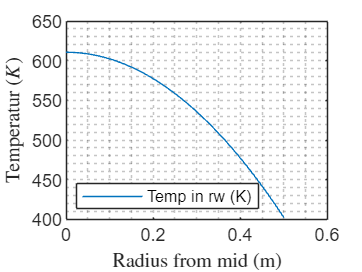


rs = linspace(0.00001, 0.499999);
double(T(rs));
plot(rs, double(T(rs)), 'DisplayName','Temp in rw (K)')
grid('minor')
ylabel("Temperatur $(K)$", Interpreter="latex")
xlabel("Radius from mid (m)", Interpreter="latex")
% help legend
legend('Location','southwest')

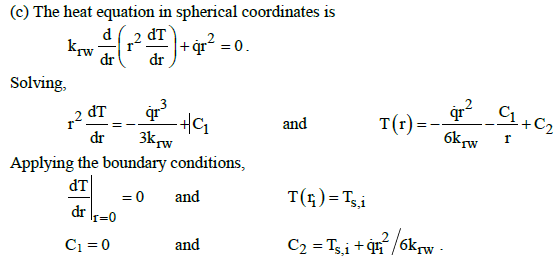

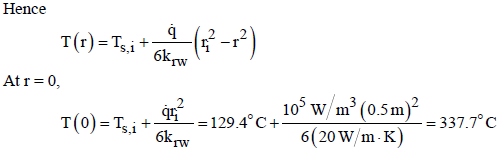

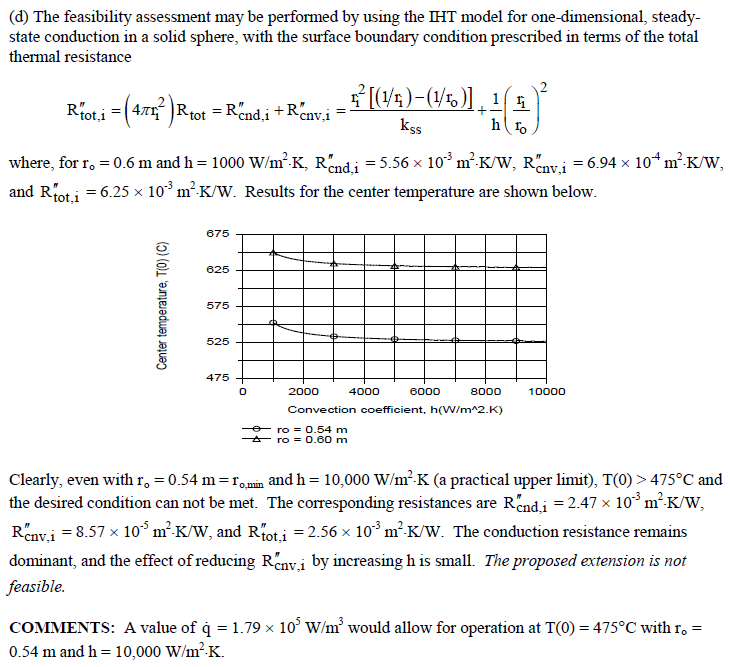

**3.102**

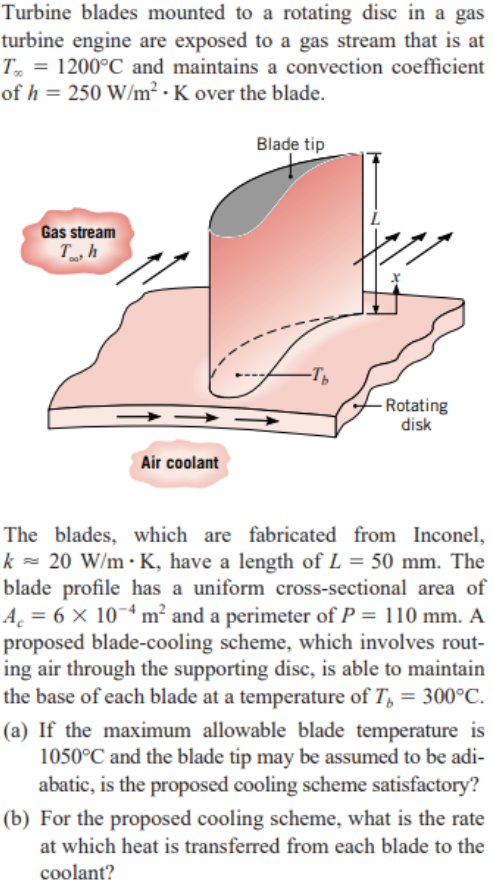

(1) One-dimensional, steady-state conduction in blade, 

(2) Constant k, 

(3) Adiabatic blade tip, 

(4) Negligible radiation.

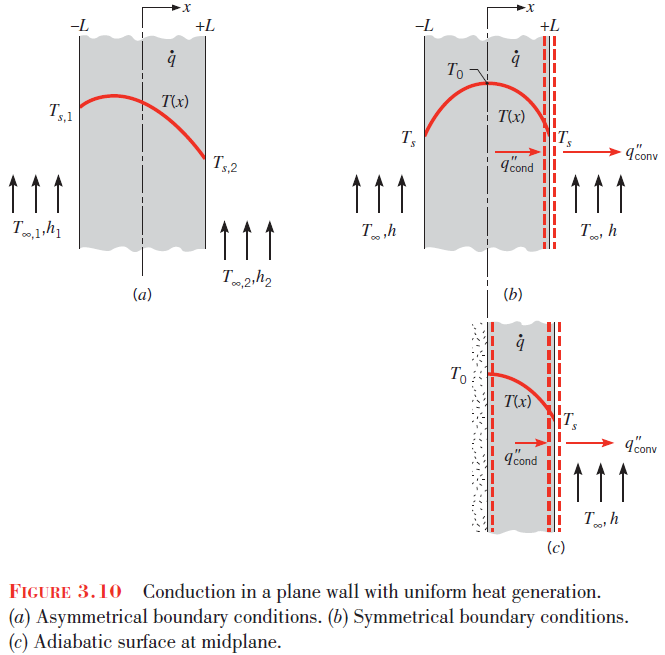

clear all
clf
k = 20; %W/m K
L = 0.050; %m
Ac = 6e-4; %m^2
P = 0.110; %m
h = 250; %W/m^2 K Gass stream
Tinf = 1200 + 273.15; % K  Gass stream
Tb = 300 + 273.15; % K
Tmax = 1050 + 273.15; % K

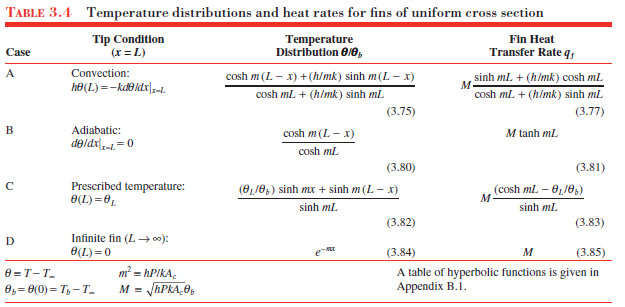

$\theta_L = T-T_{\infty}$  (temperatur forskellen fra enden af finnen(L) til der hvor luft strømmen er upåvirkede af overfladen)

h er konvections varmetallet

P er perimeter (omkredsen af finden i tværsnittet)

k er thermal conductivity, W/m ⋅ K

Ac er tværsnits arealet (for at bruge tabel 3.4)

**a)**

% q = Ac*h*(Tinf - Tmax)

format long g
syms T_sym
x = linspace(0,L,100);%L;
m = sqrt(h * P / (k*Ac))

m =           47.8713553878169


Vi finder varmen ud igennem finnnen

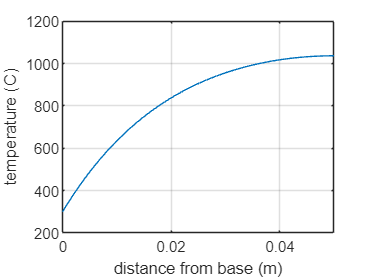

for i = 1:length(x)
    T_eq = (T_sym - Tinf)/(Tb - Tinf) == cosh( m*(L - x(i)) ) / cosh(m*L);
    T(i) = vpa(solve(T_eq, T_sym)  - 273.15 , 10);
end
T = double(T);
plot(x, T)
ylabel('temperature (C)')
xlabel('distance from base (m)')
grid('on')


T_tip = max(T)

T_tip =           1037.01267658474


Tmax

Tmax =                    1323.15


**b)**

theta_b = Tb - Tinf;
M = sqrt(h*P*k*Ac)*theta_b

M =          -517.010638188423


qf = M * tanh(m*L)

qf =          -508.461988445505


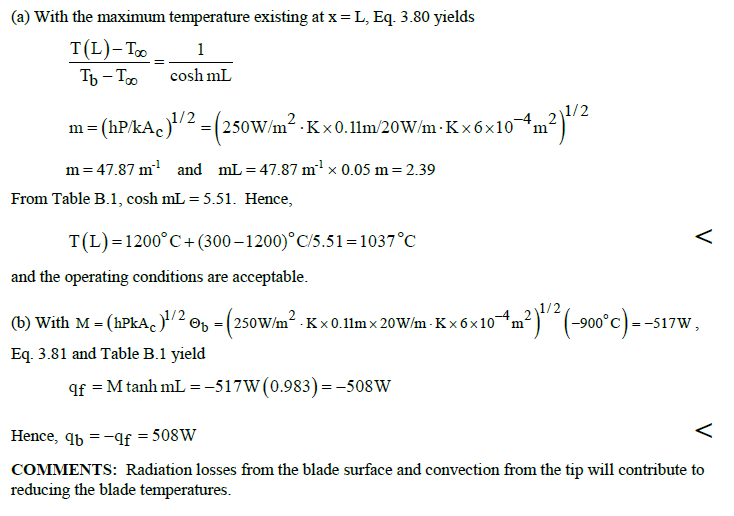

**3.144**

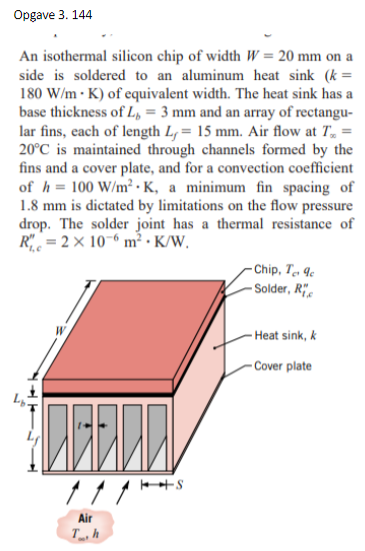

clear all
clf
format short g
CoolProp = py.importlib.import_module('CoolProp.CoolProp');
P_atm = 101325; % Pascal eller 1e5
fluid = 'air'
K = 273.15;

W = 0.02; % m %width
k = 180; % W/(m*K) % konductivitet
Lb = 0.003; % base thickness
Lf = 0.015; % m længde af  finnerne
T_inf = 20 + K; % 
T_c = 85 + K; % chiptemperatur
h = 100; % W/(m^2 * K) % convetion coeffecient
fin_space = 0.0018; % afstand imellem
R_rc = 2e-6; % m^2*K / W % samlings modstanden
syms T_b
R_b = 1/(k*(T_c-T_b))
% R_fin = 
R_tot = R_rc + R_b
q_c = (T_c - T_inf) / R_tot


$$E_{ind} - E_{ud} + E_{gen}= 0$$


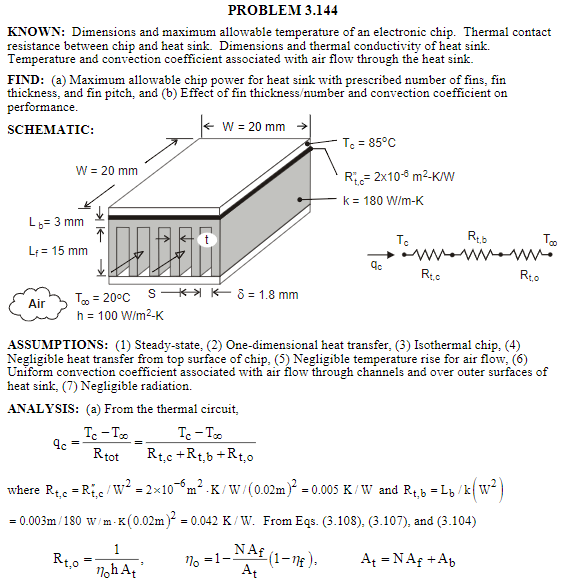

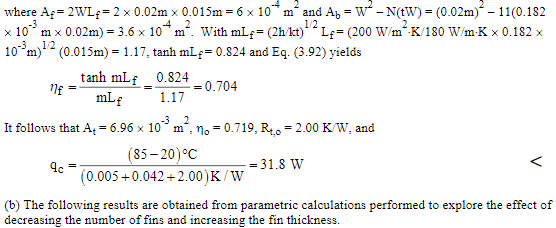

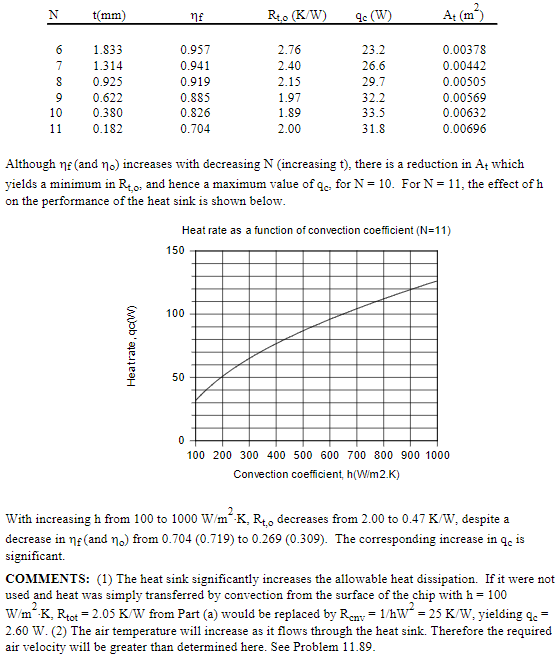

## Eksempler

eksempel 3.4

## Figurer og tabeller

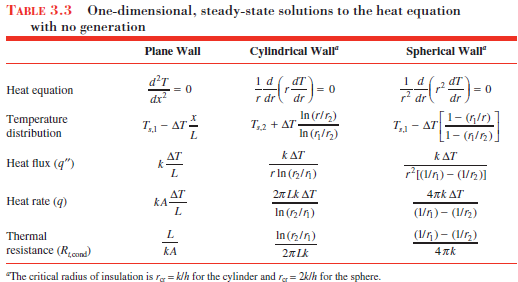

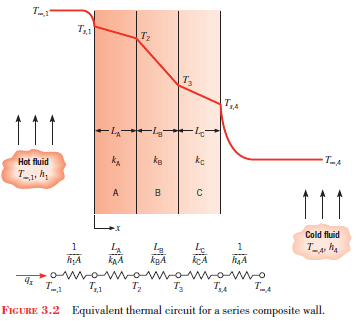

3.22 og sammenhængen til de grå formler 3.103, 3.107, 3.108, 3.109 og 3.110a